%Cassie foot force application 

clc
clear all 
close all 

syms c1 c2 r h 


%x represents the travel distance of the linear actuator
function output=calc(x)

h=.032;
r=.055;
c1=.025;
c2=.025;

%x=.02;  %m

% Define the solver function
    function [theta_sol, phi_sol, exitflag] = solveNonlinearEqs(eq1, eq2, initial_guess)
        % SOLVENONLINEAREQS Solves two nonlinear equations dependent on theta and phi
        % using optimization with bounds [0, pi/2].
        %
        % Inputs:
        %   eq1 - Anonymous function of (theta, phi) for the first equation
        %   eq2 - Anonymous function of (theta, phi) for the second equation
        %   initial_guess - [theta0, phi0], initial guess within [0, pi/2]
        %
        % Outputs:
        %   theta_sol - Solution for theta
        %   phi_sol - Solution for phi
        %   exitflag - Optimization exit flag (1 = success, others indicate issues)
        
    
        % Default initial guess if not provided
        if nargin < 3 || isempty(initial_guess)
            initial_guess = [pi/4, pi/4] % Midpoint of [0, pi/2]
        end
    
        % Validate initial guess
        if any(initial_guess < 0) || any(initial_guess > pi/2)
            error('Initial guess must be within [0, pi/2].');
        end
    
        % Define the objective function (sum of squared residuals)
        objective = @(x) (eq1(x(1), x(2))^2 + eq2(x(1), x(2))^2);
    
        % Bounds for theta and phi: [0, pi/2]
        lb = [0, 0];      % Lower bounds
        ub = [pi/2, pi/2]; % Upper bounds
    
        % Optimization options (optional: display iterations)
        options = optimoptions('fmincon', ...
            'Display', 'iter', ... % Show iteration progress
            'Algorithm', 'sqp', ... % Sequential quadratic programming
            'TolFun', 1e-8, ...    % Function tolerance
            'TolX', 1e-8);         % Step size tolerance
    
        % Solve using fmincon
        [x, ~, exitflag] = fmincon(objective, initial_guess, [], [], [], [], ...
                                   lb, ub, [], options);
    
        % Extract solutions
        theta_sol = x(1);
        phi_sol = x(2);
    
        % Verify solution (optional)
        residual1 = eq1(theta_sol, phi_sol);
        residual2 = eq2(theta_sol, phi_sol);
        fprintf('Solution: theta = %.6f, phi = %.6f\n', rad2deg(theta_sol), rad2deg(phi_sol));
        fprintf('Residuals: eq1 = %.2e, eq2 = %.2e\n', residual1, residual2);
        if exitflag <= 0
            warning('Optimization did not converge successfully (exitflag = %d).', exitflag);
        end
    end


%Equation 1 
%angle of tarsal segment relation with theta and phi
psi=@(theta, phi) phi+asin(h/c2*sin(phi));

%Equation 2 
eq1=@(theta, phi) c2/r-sin(theta)*sin(phi)/(sin(pi)-(phi+asin(h/c2*sin(phi))));

%Equaiton 3 
eq2=@(theta, phi) cos(phi)*cos(theta)-(c1-x)/r;

[theta_sol, phi_sol, exitflag]=solveNonlinearEqs(eq1, eq2)

output=[rad2deg(theta_sol) rad2deg(phi_sol)];
end 

x=linspace(0,.053);

thet_vals=[];
phi_vals=[];

vals=[];

for i = 1 : length(x)
    aa=[];
    a= calc(x(i));
    aa=[x(i) (a)];
    vals=[vals transpose(aa)];
end 

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.138189e-01     0.000e+00     1.000e+00     0.000e+00     3.277e-01  
Objective function returned complex; trying a new point...
    1           9    4.425987e-01     0.000e+00     3.430e-01     1.481e-01     5.829e-01  
Objective function returned complex; trying a new point...
    2          23    4.266048e-01     0.000e+00     1.977e-02     1.900e-02     1.911e+00  
Objective function returned complex; trying a new point...
    3          44    4.228471e-01     0.000e+00     1.628e-03     1.532e-03     8.515e+00  
Objective function returned complex; trying a new point...
    4          74    4.223225e-01     0.000e+00     6.571e-05     6.173e-05     1.789e+01  
Objective function returned complex; trying a new point...
    5         108    4.220521e-01     0.000e+00     1.578e-05  

theta_sol = 0.6586

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.147985e-01     0.000e+00     1.000e+00     0.000e+00     3.180e-01  
Objective function returned complex; trying a new point...
    1           9    4.424488e-01     0.000e+00     3.430e-01     1.479e-01     6.667e-01  
Objective function returned complex; trying a new point...
    2          24    4.311726e-01     0.000e+00     1.384e-02     1.282e-02     1.507e+00  
Objective function returned complex; trying a new point...
    3          44    4.274666e-01     0.000e+00     2.326e-03     2.123e-03     3.373e+00  
Objective function returned complex; trying a new point...
    4          68    4.249782e-01     0.000e+00     5.585e-04     5.085e-04     5.362e+01  
Objective function returned complex; trying a new point...
    5         108    4.248820e-01     0.000e+00     1.856e-06  

theta_sol = 0.6659

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.159676e-01     0.000e+00     1.000e+00     0.000e+00     3.082e-01  
Objective function returned complex; trying a new point...
    1           9    4.420514e-01     0.000e+00     3.430e-01     1.477e-01     7.934e-01  
Objective function returned complex; trying a new point...
    2          25    4.332617e-01     0.000e+00     9.689e-03     8.662e-03     1.747e+00  
Objective function returned complex; trying a new point...
    3          46    4.304586e-01     0.000e+00     1.628e-03     1.441e-03     3.365e+00  
Objective function returned complex; trying a new point...
    4          70    4.282459e-01     0.000e+00     5.585e-04     4.933e-04     1.736e+01  
Objective function returned complex; trying a new point...
    5         104    4.279994e-01     0.000e+00     1.578e-05  

theta_sol = 0.6728

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.173262e-01     0.000e+00     1.000e+00     0.000e+00     3.105e-01  
Objective function returned complex; trying a new point...
    1           9    4.411744e-01     0.000e+00     3.430e-01     1.477e-01     1.029e+00  
Objective function returned complex; trying a new point...
    2          26    4.323560e-01     0.000e+00     6.782e-03     5.861e-03     5.336e+00  
Objective function returned complex; trying a new point...
    3          53    4.313648e-01     0.000e+00     1.916e-04     1.643e-04     1.237e+01  
Objective function returned complex; trying a new point...
    4          85    4.310039e-01     0.000e+00     3.220e-05     2.761e-05     2.438e+01  
Objective function returned complex; trying a new point...
    5         120    4.306663e-01     0.000e+00     1.104e-05  

theta_sol = 0.6793

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.188743e-01     0.000e+00     1.000e+00     0.000e+00     3.202e-01  
Objective function returned complex; trying a new point...
    1           9    4.389720e-01     0.000e+00     3.430e-01     1.479e-01     1.848e+00  
Objective function returned complex; trying a new point...
    2          30    4.360281e-01     0.000e+00     1.628e-03     1.362e-03     3.794e+00  
Objective function returned complex; trying a new point...
    3          55    4.345838e-01     0.000e+00     3.910e-04     3.263e-04     8.714e+00  
Objective function returned complex; trying a new point...
    4          85    4.340661e-01     0.000e+00     6.571e-05     5.481e-05     1.687e+01  
Objective function returned complex; trying a new point...
    5         118    4.336448e-01     0.000e+00     2.254e-05  

theta_sol = 0.6853

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.206119e-01     0.000e+00     1.000e+00     0.000e+00     3.300e-01  
Objective function returned complex; trying a new point...
    1          10    4.712914e-01     0.000e+00     2.401e-01     1.038e-01     4.841e-01  
Objective function returned complex; trying a new point...
    2          22    4.462888e-01     0.000e+00     4.035e-02     3.584e-02     1.202e+00  
Objective function returned complex; trying a new point...
    3          40    4.397398e-01     0.000e+00     4.748e-03     4.047e-03     3.813e+00  
Objective function returned complex; trying a new point...
    4          65    4.382867e-01     0.000e+00     3.910e-04     3.316e-04     8.630e+00  
Objective function returned complex; trying a new point...
    5          95    4.377819e-01     0.000e+00     6.571e-05  

theta_sol = 0.6940

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.225390e-01     0.000e+00     1.000e+00     0.000e+00     3.397e-01  
Objective function returned complex; trying a new point...
    1          10    4.724655e-01     0.000e+00     2.401e-01     1.041e-01     5.087e-01  
Objective function returned complex; trying a new point...
    2          22    4.454100e-01     0.000e+00     4.035e-02     3.496e-02     1.965e+00  
Objective function returned complex; trying a new point...
    3          43    4.421105e-01     0.000e+00     1.628e-03     1.353e-03     4.897e+00  
Objective function returned complex; trying a new point...
    4          69    4.406749e-01     0.000e+00     2.737e-04     2.270e-04     1.684e+01  
Objective function returned complex; trying a new point...
    5         102    4.402802e-01     0.000e+00     2.254e-05  

theta_sol = 0.6994

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.246555e-01     0.000e+00     1.000e+00     0.000e+00     3.494e-01  
Objective function returned complex; trying a new point...
    1          10    4.737047e-01     0.000e+00     2.401e-01     1.045e-01     5.354e-01  
Objective function returned complex; trying a new point...
    2          23    4.571230e-01     0.000e+00     2.825e-02     2.390e-02     8.821e-01  
Objective function returned complex; trying a new point...
    3          39    4.475681e-01     0.000e+00     9.689e-03     7.970e-03     2.316e+00  
Objective function returned complex; trying a new point...
    4          61    4.449495e-01     0.000e+00     1.140e-03     9.283e-04     5.274e+00  
Objective function returned complex; trying a new point...
    5          88    4.440287e-01     0.000e+00     1.916e-04  

theta_sol = 0.7046

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.269616e-01     0.000e+00     1.000e+00     0.000e+00     3.592e-01  
Objective function returned complex; trying a new point...
    1          10    4.750037e-01     0.000e+00     2.401e-01     1.051e-01     5.644e-01  
Objective function returned complex; trying a new point...
    2          23    4.575775e-01     0.000e+00     2.825e-02     2.338e-02     1.050e+00  
Objective function returned complex; trying a new point...
    3          40    4.498589e-01     0.000e+00     6.782e-03     5.455e-03     2.766e+00  
Objective function returned complex; trying a new point...
    4          63    4.477182e-01     0.000e+00     7.979e-04     6.373e-04     6.115e+00  
Objective function returned complex; trying a new point...
    5          90    4.463576e-01     0.000e+00     1.916e-04  

theta_sol = 0.7096

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.294571e-01     0.000e+00     1.000e+00     0.000e+00     3.689e-01  
Objective function returned complex; trying a new point...
    1          10    4.763559e-01     0.000e+00     2.401e-01     1.057e-01     5.966e-01  
Objective function returned complex; trying a new point...
    2          23    4.576009e-01     0.000e+00     2.825e-02     2.290e-02     1.376e+00  
Objective function returned complex; trying a new point...
    3          42    4.531977e-01     0.000e+00     3.323e-03     2.617e-03     2.637e+00  
Objective function returned complex; trying a new point...
    4          65    4.512787e-01     0.000e+00     7.979e-04     6.261e-04     4.823e+00  
Objective function returned complex; trying a new point...
    5          91    4.499838e-01     0.000e+00     2.737e-04  

theta_sol = 0.7143

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.321422e-01     0.000e+00     1.000e+00     0.000e+00     3.786e-01  
Objective function returned complex; trying a new point...
    1          10    4.777532e-01     0.000e+00     2.401e-01     1.064e-01     6.327e-01  
Objective function returned complex; trying a new point...
    2          23    4.562963e-01     0.000e+00     2.825e-02     2.246e-02     2.703e+00  
Objective function returned complex; trying a new point...
    3          46    4.543201e-01     0.000e+00     7.979e-04     6.157e-04     5.110e+00  
Objective function returned complex; trying a new point...
    4          72    4.528182e-01     0.000e+00     2.737e-04     2.110e-04     1.868e+01  
Objective function returned complex; trying a new point...
    5         106    4.525551e-01     0.000e+00     1.578e-05  

theta_sol = 0.7187

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.350167e-01     0.000e+00     1.000e+00     0.000e+00     3.884e-01  
Objective function returned complex; trying a new point...
    1          10    4.791846e-01     0.000e+00     2.401e-01     1.072e-01     6.739e-01  
Objective function returned complex; trying a new point...
    2          24    4.659122e-01     0.000e+00     1.977e-02     1.544e-02     1.199e+00  
Objective function returned complex; trying a new point...
    3          42    4.604979e-01     0.000e+00     4.748e-03     3.631e-03     2.242e+00  
Objective function returned complex; trying a new point...
    4          63    4.559671e-01     0.000e+00     1.628e-03     1.239e-03     2.134e+01  
Objective function returned complex; trying a new point...
    5          97    4.555991e-01     0.000e+00     1.578e-05  

theta_sol = 0.7230

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.380807e-01     0.000e+00     1.000e+00     0.000e+00     3.981e-01  
Objective function returned complex; trying a new point...
    1          10    4.806360e-01     0.000e+00     2.401e-01     1.082e-01     7.222e-01  
Objective function returned complex; trying a new point...
    2          24    4.657363e-01     0.000e+00     1.977e-02     1.517e-02     1.707e+00  
Objective function returned complex; trying a new point...
    3          44    4.619895e-01     0.000e+00     2.326e-03     1.748e-03     3.426e+00  
Objective function returned complex; trying a new point...
    4          68    4.601700e-01     0.000e+00     5.585e-04     4.187e-04     7.614e+00  
Objective function returned complex; trying a new point...
    5          96    4.589104e-01     0.000e+00     1.341e-04  

theta_sol = 0.7271

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.413342e-01     0.000e+00     1.000e+00     0.000e+00     4.078e-01  
Objective function returned complex; trying a new point...
    1          10    4.820873e-01     0.000e+00     2.401e-01     1.092e-01     7.804e-01  
Objective function returned complex; trying a new point...
    2          25    4.719871e-01     0.000e+00     1.384e-02     1.045e-02     1.301e+00  
Objective function returned complex; trying a new point...
    3          43    4.658623e-01     0.000e+00     4.748e-03     3.532e-03     3.043e+00  
Objective function returned complex; trying a new point...
    4          66    4.633946e-01     0.000e+00     7.979e-04     5.907e-04     8.666e+00  
Objective function returned complex; trying a new point...
    5          95    4.625682e-01     0.000e+00     9.387e-05  

theta_sol = 0.7310

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.447772e-01     0.000e+00     1.000e+00     0.000e+00     4.176e-01  
Objective function returned complex; trying a new point...
    1          10    4.835097e-01     0.000e+00     2.401e-01     1.103e-01     8.538e-01  
Objective function returned complex; trying a new point...
    2          25    4.716497e-01     0.000e+00     1.384e-02     1.029e-02     1.997e+00  
Objective function returned complex; trying a new point...
    3          46    4.687183e-01     0.000e+00     1.628e-03     1.193e-03     3.657e+00  
Objective function returned complex; trying a new point...
    4          70    4.666378e-01     0.000e+00     5.585e-04     4.083e-04     1.077e+01  
Objective function returned complex; trying a new point...
    5         100    4.658528e-01     0.000e+00     6.571e-05  

theta_sol = 0.7348

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.484097e-01     0.000e+00     1.000e+00     0.000e+00     4.273e-01  
Objective function returned complex; trying a new point...
    1          10    4.848573e-01     0.000e+00     2.401e-01     1.115e-01     9.518e-01  
Objective function returned complex; trying a new point...
    2          26    4.762964e-01     0.000e+00     9.689e-03     7.098e-03     1.760e+00  
Objective function returned complex; trying a new point...
    3          46    4.725222e-01     0.000e+00     2.326e-03     1.686e-03     3.467e+00  
Objective function returned complex; trying a new point...
    4          70    4.707273e-01     0.000e+00     5.585e-04     4.039e-04     7.281e+00  
Objective function returned complex; trying a new point...
    5          98    4.697595e-01     0.000e+00     1.341e-04  

theta_sol = 0.7384

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.522317e-01     0.000e+00     1.000e+00     0.000e+00     4.370e-01  
Objective function returned complex; trying a new point...
    1          10    4.860508e-01     0.000e+00     2.401e-01     1.128e-01     1.096e+00  
Objective function returned complex; trying a new point...
    2          27    4.793638e-01     0.000e+00     6.782e-03     4.900e-03     1.929e+00  
Objective function returned complex; trying a new point...
    3          47    4.746956e-01     0.000e+00     2.326e-03     1.668e-03     6.231e+00  
Objective function returned complex; trying a new point...
    4          74    4.734872e-01     0.000e+00     1.916e-04     1.370e-04     1.846e+01  
Objective function returned complex; trying a new point...
    5         107    4.730296e-01     0.000e+00     2.254e-05  

theta_sol = 0.7419

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.562431e-01     0.000e+00     1.000e+00     0.000e+00     4.468e-01  
Objective function returned complex; trying a new point...
    1          10    4.869258e-01     0.000e+00     2.401e-01     1.141e-01     1.345e+00  
Objective function returned complex; trying a new point...
    2          28    4.809650e-01     0.000e+00     4.748e-03     3.384e-03     2.811e+00  
Objective function returned complex; trying a new point...
    3          50    4.770678e-01     0.000e+00     1.140e-03     8.081e-04     2.877e+01  
Objective function returned complex; trying a new point...
    4          86    4.768628e-01     0.000e+00     7.731e-06     5.473e-06     6.222e+01  
Objective function returned complex; trying a new point...
    5         126    4.767468e-01     0.000e+00     1.856e-06  

theta_sol = 0.7452

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.604441e-01     0.000e+00     1.000e+00     0.000e+00     4.565e-01  
Objective function returned complex; trying a new point...
    1          10    4.869934e-01     0.000e+00     2.401e-01     1.156e-01     2.001e+00  
Objective function returned complex; trying a new point...
    2          30    4.819816e-01     0.000e+00     2.326e-03     1.636e-03     8.139e+00  
Objective function returned complex; trying a new point...
    3          59    4.813022e-01     0.000e+00     9.387e-05     6.583e-05     1.562e+01  
Objective function returned complex; trying a new point...
    4          91    4.807522e-01     0.000e+00     3.220e-05     2.258e-05     6.751e+01  
Objective function returned complex; trying a new point...
    5         132    4.806751e-01     0.000e+00     1.299e-06  

theta_sol = 0.7483

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.648345e-01     0.000e+00     1.000e+00     0.000e+00     4.662e-01  
Objective function returned complex; trying a new point...
    1          11    5.201029e-01     0.000e+00     1.681e-01     8.195e-02     6.302e-01  
Objective function returned complex; trying a new point...
    2          23    4.950788e-01     0.000e+00     4.035e-02     3.069e-02     1.299e+00  
Objective function returned complex; trying a new point...
    3          41    4.894729e-01     0.000e+00     4.748e-03     3.468e-03     2.346e+00  
Objective function returned complex; trying a new point...
    4          62    4.852492e-01     0.000e+00     1.628e-03     1.184e-03     1.030e+01  
Objective function returned complex; trying a new point...
    5          92    4.846010e-01     0.000e+00     6.571e-05  

theta_sol = 0.7483

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.694145e-01     0.000e+00     1.000e+00     0.000e+00     4.760e-01  
Objective function returned complex; trying a new point...
    1          11    5.233050e-01     0.000e+00     1.681e-01     8.306e-02     6.503e-01  
Objective function returned complex; trying a new point...
    2          23    4.969265e-01     0.000e+00     4.035e-02     3.041e-02     1.589e+00  
Objective function returned complex; trying a new point...
    3          42    4.919697e-01     0.000e+00     3.323e-03     2.404e-03     3.329e+00  
Objective function returned complex; trying a new point...
    4          65    4.889320e-01     0.000e+00     7.979e-04     5.750e-04     1.863e+01  
Objective function returned complex; trying a new point...
    5          98    4.884787e-01     0.000e+00     2.254e-05  

theta_sol = 0.7513

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.741839e-01     0.000e+00     1.000e+00     0.000e+00     4.857e-01  
Objective function returned complex; trying a new point...
    1          11    5.266171e-01     0.000e+00     1.681e-01     8.422e-02     6.714e-01  
Objective function returned complex; trying a new point...
    2          23    4.981936e-01     0.000e+00     4.035e-02     3.014e-02     2.314e+00  
Objective function returned complex; trying a new point...
    3          44    4.943969e-01     0.000e+00     1.628e-03     1.166e-03     6.613e+00  
Objective function returned complex; trying a new point...
    4          71    4.929781e-01     0.000e+00     1.916e-04     1.369e-04     3.256e+01  
Objective function returned complex; trying a new point...
    5         107    4.926800e-01     0.000e+00     7.731e-06  

theta_sol = 0.7542

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.791428e-01     0.000e+00     1.000e+00     0.000e+00     4.955e-01  
Objective function returned complex; trying a new point...
    1          11    5.300376e-01     0.000e+00     1.681e-01     8.543e-02     6.936e-01  
Objective function returned complex; trying a new point...
    2          24    5.128188e-01     0.000e+00     2.825e-02     2.091e-02     1.045e+00  
Objective function returned complex; trying a new point...
    3          40    5.033766e-01     0.000e+00     9.689e-03     6.977e-03     2.096e+00  
Objective function returned complex; trying a new point...
    4          61    5.003702e-01     0.000e+00     1.628e-03     1.161e-03     3.706e+00  
Objective function returned complex; trying a new point...
    5          85    4.983933e-01     0.000e+00     5.585e-04  

theta_sol = 0.7569

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.842912e-01     0.000e+00     1.000e+00     0.000e+00     5.052e-01  
Objective function returned complex; trying a new point...
    1          11    5.335646e-01     0.000e+00     1.681e-01     8.668e-02     7.169e-01  
Objective function returned complex; trying a new point...
    2          24    5.156267e-01     0.000e+00     2.825e-02     2.074e-02     1.150e+00  
Objective function returned complex; trying a new point...
    3          41    5.088112e-01     0.000e+00     6.782e-03     4.842e-03     1.907e+00  
Objective function returned complex; trying a new point...
    4          61    5.046856e-01     0.000e+00     2.326e-03     1.649e-03     4.029e+00  
Objective function returned complex; trying a new point...
    5          85    5.020689e-01     0.000e+00     5.585e-04  

theta_sol = 0.7596

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.896291e-01     0.000e+00     1.000e+00     0.000e+00     5.149e-01  
Objective function returned complex; trying a new point...
    1          11    5.371961e-01     0.000e+00     1.681e-01     8.798e-02     7.416e-01  
Objective function returned complex; trying a new point...
    2          24    5.183712e-01     0.000e+00     2.825e-02     2.058e-02     1.297e+00  
Objective function returned complex; trying a new point...
    3          41    5.093786e-01     0.000e+00     6.782e-03     4.802e-03     4.086e+00  
Objective function returned complex; trying a new point...
    4          65    5.065602e-01     0.000e+00     5.585e-04     3.926e-04     5.228e+01  
Objective function returned complex; trying a new point...
    5         104    5.064259e-01     0.000e+00     2.652e-06  

theta_sol = 0.7623

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    5.951565e-01     0.000e+00     1.000e+00     0.000e+00     5.247e-01  
Objective function returned complex; trying a new point...
    1          11    5.409294e-01     0.000e+00     1.681e-01     8.931e-02     7.679e-01  
Objective function returned complex; trying a new point...
    2          24    5.209532e-01     0.000e+00     2.825e-02     2.042e-02     1.534e+00  
Objective function returned complex; trying a new point...
    3          42    5.132553e-01     0.000e+00     4.748e-03     3.335e-03     5.886e+00  
Objective function returned complex; trying a new point...
    4          69    5.122604e-01     0.000e+00     1.916e-04     1.338e-04     1.100e+01  
Objective function returned complex; trying a new point...
    5          99    5.115229e-01     0.000e+00     6.571e-05  

theta_sol = 0.7649

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.008734e-01     0.000e+00     1.000e+00     0.000e+00     5.344e-01  
Objective function returned complex; trying a new point...
    1          11    5.447616e-01     0.000e+00     1.681e-01     9.069e-02     7.962e-01  
Objective function returned complex; trying a new point...
    2          24    5.231299e-01     0.000e+00     2.825e-02     2.028e-02     2.028e+00  
Objective function returned complex; trying a new point...
    3          44    5.185503e-01     0.000e+00     2.326e-03     1.621e-03     5.208e+00  
Objective function returned complex; trying a new point...
    4          70    5.172368e-01     0.000e+00     2.737e-04     1.902e-04     1.116e+01  
Objective function returned complex; trying a new point...
    5         100    5.164728e-01     0.000e+00     6.571e-05  

theta_sol = 0.7674

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.067797e-01     0.000e+00     1.000e+00     0.000e+00     5.441e-01  
Objective function returned complex; trying a new point...
    1          11    5.486893e-01     0.000e+00     1.681e-01     9.210e-02     8.269e-01  
Objective function returned complex; trying a new point...
    2          24    5.235901e-01     0.000e+00     2.825e-02     2.014e-02     5.434e+00  
Objective function returned complex; trying a new point...
    3          50    5.221490e-01     0.000e+00     2.737e-04     1.892e-04     1.393e+01  
Objective function returned complex; trying a new point...
    4          82    5.212949e-01     0.000e+00     4.600e-05     3.179e-05     1.053e+03  
Objective function returned complex; trying a new point...
    5         133    5.212949e-01     0.000e+00     1.259e-08  

theta_sol = 0.7698

phi_sol = 0.8967

exitflag = 2

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.128756e-01     0.000e+00     1.000e+00     0.000e+00     5.539e-01  
Objective function returned complex; trying a new point...
    1          11    5.527081e-01     0.000e+00     1.681e-01     9.355e-02     8.603e-01  
Objective function returned complex; trying a new point...
    2          25    5.381354e-01     0.000e+00     1.977e-02     1.400e-02     1.408e+00  
Objective function returned complex; trying a new point...
    3          43    5.323802e-01     0.000e+00     4.748e-03     3.294e-03     2.400e+00  
Objective function returned complex; trying a new point...
    4          64    5.286080e-01     0.000e+00     1.628e-03     1.124e-03     6.095e+00  
Objective function returned complex; trying a new point...
    5          91    5.275597e-01     0.000e+00     1.916e-04  

theta_sol = 0.7722

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.191609e-01     0.000e+00     1.000e+00     0.000e+00     5.636e-01  
Objective function returned complex; trying a new point...
    1          11    5.568127e-01     0.000e+00     1.681e-01     9.503e-02     8.974e-01  
Objective function returned complex; trying a new point...
    2          25    5.410801e-01     0.000e+00     1.977e-02     1.392e-02     1.700e+00  
Objective function returned complex; trying a new point...
    3          44    5.360377e-01     0.000e+00     3.323e-03     2.291e-03     3.296e+00  
Objective function returned complex; trying a new point...
    4          67    5.335398e-01     0.000e+00     7.979e-04     5.480e-04     7.902e+00  
Objective function returned complex; trying a new point...
    5          95    5.324649e-01     0.000e+00     1.341e-04  

theta_sol = 0.7745

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.256357e-01     0.000e+00     1.000e+00     0.000e+00     5.733e-01  
Objective function returned complex; trying a new point...
    1          11    5.609966e-01     0.000e+00     1.681e-01     9.654e-02     9.389e-01  
Objective function returned complex; trying a new point...
    2          25    5.434342e-01     0.000e+00     1.977e-02     1.383e-02     2.424e+00  
Objective function returned complex; trying a new point...
    3          46    5.396804e-01     0.000e+00     1.628e-03     1.115e-03     5.918e+00  
Objective function returned complex; trying a new point...
    4          72    5.376824e-01     0.000e+00     2.737e-04     1.871e-04     7.794e+01  
Objective function returned complex; trying a new point...
    5         113    5.375808e-01     0.000e+00     1.299e-06  

theta_sol = 0.7768

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.323001e-01     0.000e+00     1.000e+00     0.000e+00     5.831e-01  
Objective function returned complex; trying a new point...
    1          11    5.652512e-01     0.000e+00     1.681e-01     9.809e-02     9.862e-01  
Objective function returned complex; trying a new point...
    2          26    5.538710e-01     0.000e+00     1.384e-02     9.629e-03     1.554e+00  
Objective function returned complex; trying a new point...
    3          44    5.469907e-01     0.000e+00     4.748e-03     3.255e-03     3.599e+00  
Objective function returned complex; trying a new point...
    4          67    5.434917e-01     0.000e+00     7.979e-04     5.442e-04     4.686e+01  
Objective function returned complex; trying a new point...
    5         105    5.433034e-01     0.000e+00     3.788e-06  

theta_sol = 0.7790

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.391539e-01     0.000e+00     1.000e+00     0.000e+00     5.928e-01  
Objective function returned complex; trying a new point...
    1          11    5.695653e-01     0.000e+00     1.681e-01     9.967e-02     1.041e+00  
Objective function returned complex; trying a new point...
    2          26    5.569391e-01     0.000e+00     1.384e-02     9.578e-03     1.971e+00  
Objective function returned complex; trying a new point...
    3          46    5.529734e-01     0.000e+00     2.326e-03     1.586e-03     3.526e+00  
Objective function returned complex; trying a new point...
    4          69    5.500094e-01     0.000e+00     7.979e-04     5.426e-04     1.346e+01  
Objective function returned complex; trying a new point...
    5         100    5.493805e-01     0.000e+00     4.600e-05  

theta_sol = 0.7811

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.461972e-01     0.000e+00     1.000e+00     0.000e+00     6.025e-01  
Objective function returned complex; trying a new point...
    1          11    5.739237e-01     0.000e+00     1.681e-01     1.013e-01     1.108e+00  
Objective function returned complex; trying a new point...
    2          26    5.588475e-01     0.000e+00     1.384e-02     9.531e-03     3.667e+00  
Objective function returned complex; trying a new point...
    3          50    5.570823e-01     0.000e+00     5.585e-04     3.789e-04     6.514e+00  
Objective function returned complex; trying a new point...
    4          77    5.559063e-01     0.000e+00     1.916e-04     1.299e-04     1.529e+01  
Objective function returned complex; trying a new point...
    5         109    5.554462e-01     0.000e+00     3.220e-05  

theta_sol = 0.7832

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.534300e-01     0.000e+00     1.000e+00     0.000e+00     6.123e-01  
Objective function returned complex; trying a new point...
    1          11    5.783045e-01     0.000e+00     1.681e-01     1.029e-01     1.190e+00  
Objective function returned complex; trying a new point...
    2          27    5.683482e-01     0.000e+00     9.689e-03     6.642e-03     2.179e+00  
Objective function returned complex; trying a new point...
    3          47    5.634056e-01     0.000e+00     2.326e-03     1.578e-03     6.091e+00  
Objective function returned complex; trying a new point...
    4          74    5.623907e-01     0.000e+00     1.916e-04     1.296e-04     1.110e+01  
Objective function returned complex; trying a new point...
    5         104    5.616853e-01     0.000e+00     6.571e-05  

theta_sol = 0.7852

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.608523e-01     0.000e+00     1.000e+00     0.000e+00     6.220e-01  
Objective function returned complex; trying a new point...
    1          11    5.826743e-01     0.000e+00     1.681e-01     1.046e-01     1.297e+00  
Objective function returned complex; trying a new point...
    2          27    5.694096e-01     0.000e+00     9.689e-03     6.614e-03     7.078e+00  
Objective function returned complex; trying a new point...
    3          54    5.678841e-01     0.000e+00     1.916e-04     1.294e-04     3.846e+01  
Objective function returned complex; trying a new point...
    4          91    5.676784e-01     0.000e+00     5.412e-06     3.654e-06     1.070e+02  
Objective function returned complex; trying a new point...
    5         134    5.676158e-01     0.000e+00     6.367e-07  

theta_sol = 0.7871

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.684640e-01     0.000e+00     1.000e+00     0.000e+00     6.317e-01  
Objective function returned complex; trying a new point...
    1          11    5.869779e-01     0.000e+00     1.681e-01     1.062e-01     1.449e+00  
Objective function returned complex; trying a new point...
    2          28    5.776514e-01     0.000e+00     6.782e-03     4.613e-03     3.878e+00  
Objective function returned complex; trying a new point...
    3          52    5.757140e-01     0.000e+00     5.585e-04     3.772e-04     7.764e+00  
Objective function returned complex; trying a new point...
    4          80    5.747420e-01     0.000e+00     1.341e-04     9.049e-05     1.769e+01  
Objective function returned complex; trying a new point...
    5         113    5.743856e-01     0.000e+00     2.254e-05  

theta_sol = 0.7890

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.762653e-01     0.000e+00     1.000e+00     0.000e+00     6.415e-01  
Objective function returned complex; trying a new point...
    1          11    5.911096e-01     0.000e+00     1.681e-01     1.079e-01     1.694e+00  
Objective function returned complex; trying a new point...
    2          29    5.831748e-01     0.000e+00     4.748e-03     3.218e-03     5.392e+00  
Objective function returned complex; trying a new point...
    3          55    5.818555e-01     0.000e+00     2.737e-04     1.846e-04     1.075e+01  
Objective function returned complex; trying a new point...
    4          85    5.812123e-01     0.000e+00     6.571e-05     4.431e-05     2.255e+01  
Objective function returned complex; trying a new point...
    5         119    5.808669e-01     0.000e+00     1.578e-05  

theta_sol = 0.7907

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.842560e-01     0.000e+00     1.000e+00     0.000e+00     6.512e-01  
Objective function returned complex; trying a new point...
    1          11    5.948091e-01     0.000e+00     1.681e-01     1.097e-01     2.207e+00  
Objective function returned complex; trying a new point...
    2          31    5.900111e-01     0.000e+00     2.326e-03     1.572e-03     5.328e+00  
Objective function returned complex; trying a new point...
    3          57    5.887299e-01     0.000e+00     2.737e-04     1.846e-04     1.008e+01  
Objective function returned complex; trying a new point...
    4          86    5.876563e-01     0.000e+00     9.387e-05     6.329e-05     5.711e+01  
Objective function returned complex; trying a new point...
    5         125    5.874956e-01     0.000e+00     2.652e-06  

theta_sol = 0.7925

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.924363e-01     0.000e+00     1.000e+00     0.000e+00     6.609e-01  
Objective function returned complex; trying a new point...
    1          11    5.965997e-01     0.000e+00     1.681e-01     1.114e-01     6.140e+00  
Objective function returned complex; trying a new point...
    2          37    5.945899e-01     0.000e+00     2.737e-04     1.846e-04     6.021e+01  
Objective function returned complex; trying a new point...
    3          77    5.944917e-01     0.000e+00     1.856e-06     1.252e-06     1.141e+02  
Objective function returned complex; trying a new point...
    4         120    5.944194e-01     0.000e+00     6.367e-07     4.294e-07     3.532e+02  
Objective function returned complex; trying a new point...
    5         170    5.943948e-01     0.000e+00     7.490e-08  

theta_sol = 0.7941

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.008060e-01     0.000e+00     1.000e+00     0.000e+00     6.707e-01  
Objective function returned complex; trying a new point...
    1          12    6.428294e-01     0.000e+00     1.176e-01     7.923e-02     8.477e-01  
Objective function returned complex; trying a new point...
    2          24    6.128608e-01     0.000e+00     4.035e-02     2.854e-02     1.626e+00  
Objective function returned complex; trying a new point...
    3          42    6.058281e-01     0.000e+00     4.748e-03     3.223e-03     3.456e+00  
Objective function returned complex; trying a new point...
    4          65    6.032222e-01     0.000e+00     7.979e-04     5.389e-04     8.223e+00  
Objective function returned complex; trying a new point...
    5          93    6.020881e-01     0.000e+00     1.341e-04  

theta_sol = 0.7911

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.093652e-01     0.000e+00     1.000e+00     0.000e+00     6.804e-01  
Objective function returned complex; trying a new point...
    1          12    6.495041e-01     0.000e+00     1.176e-01     8.049e-02     8.651e-01  
Objective function returned complex; trying a new point...
    2          24    6.182738e-01     0.000e+00     4.035e-02     2.848e-02     1.867e+00  
Objective function returned complex; trying a new point...
    3          43    6.126679e-01     0.000e+00     3.323e-03     2.250e-03     3.847e+00  
Objective function returned complex; trying a new point...
    4          67    6.107764e-01     0.000e+00     5.585e-04     3.769e-04     7.222e+00  
Objective function returned complex; trying a new point...
    5          94    6.091398e-01     0.000e+00     1.916e-04  

theta_sol = 0.7929

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.181139e-01     0.000e+00     1.000e+00     0.000e+00     6.901e-01  
Objective function returned complex; trying a new point...
    1          12    6.563158e-01     0.000e+00     1.176e-01     8.175e-02     8.830e-01  
Objective function returned complex; trying a new point...
    2          24    6.234767e-01     0.000e+00     4.035e-02     2.842e-02     2.311e+00  
Objective function returned complex; trying a new point...
    3          44    6.178875e-01     0.000e+00     2.326e-03     1.572e-03     8.846e+00  
Objective function returned complex; trying a new point...
    4          73    6.171542e-01     0.000e+00     9.387e-05     6.329e-05     1.679e+01  
Objective function returned complex; trying a new point...
    5         105    6.165690e-01     0.000e+00     3.220e-05  

theta_sol = 0.7946

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.270521e-01     0.000e+00     1.000e+00     0.000e+00     6.999e-01  
Objective function returned complex; trying a new point...
    1          12    6.632640e-01     0.000e+00     1.176e-01     8.303e-02     9.014e-01  
Objective function returned complex; trying a new point...
    2          24    6.279808e-01     0.000e+00     4.035e-02     2.837e-02     3.720e+00  
Objective function returned complex; trying a new point...
    3          47    6.247490e-01     0.000e+00     7.979e-04     5.384e-04     1.757e+01  
Objective function returned complex; trying a new point...
    4          80    6.244009e-01     0.000e+00     2.254e-05     1.520e-05     3.293e+01  
Objective function returned complex; trying a new point...
    5         116    6.241454e-01     0.000e+00     7.731e-06  

theta_sol = 0.7962

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.361798e-01     0.000e+00     1.000e+00     0.000e+00     7.096e-01  
Objective function returned complex; trying a new point...
    1          12    6.703480e-01     0.000e+00     1.176e-01     8.432e-02     9.204e-01  
Objective function returned complex; trying a new point...
    2          25    6.493385e-01     0.000e+00     2.825e-02     1.983e-02     1.297e+00  
Objective function returned complex; trying a new point...
    3          41    6.381891e-01     0.000e+00     9.689e-03     6.610e-03     2.544e+00  
Objective function returned complex; trying a new point...
    4          62    6.344078e-01     0.000e+00     1.628e-03     1.100e-03     5.394e+00  
Objective function returned complex; trying a new point...
    5          88    6.331041e-01     0.000e+00     2.737e-04  

theta_sol = 0.7978

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.454970e-01     0.000e+00     1.000e+00     0.000e+00     7.193e-01  
Objective function returned complex; trying a new point...
    1          12    6.775672e-01     0.000e+00     1.176e-01     8.562e-02     9.399e-01  
Objective function returned complex; trying a new point...
    2          25    6.558823e-01     0.000e+00     2.825e-02     1.981e-02     1.376e+00  
Objective function returned complex; trying a new point...
    3          41    6.423574e-01     0.000e+00     9.689e-03     6.603e-03     5.437e+00  
Objective function returned complex; trying a new point...
    4          67    6.410390e-01     0.000e+00     2.737e-04     1.847e-04     1.042e+01  
Objective function returned complex; trying a new point...
    5          97    6.404430e-01     0.000e+00     6.571e-05  

theta_sol = 0.7994

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.550037e-01     0.000e+00     1.000e+00     0.000e+00     7.291e-01  
Objective function returned complex; trying a new point...
    1          12    6.849207e-01     0.000e+00     1.176e-01     8.693e-02     9.602e-01  
Objective function returned complex; trying a new point...
    2          25    6.624791e-01     0.000e+00     2.825e-02     1.979e-02     1.474e+00  
Objective function returned complex; trying a new point...
    3          42    6.536948e-01     0.000e+00     6.782e-03     4.618e-03     2.781e+00  
Objective function returned complex; trying a new point...
    4          63    6.486246e-01     0.000e+00     1.628e-03     1.101e-03     1.749e+01  
Objective function returned complex; trying a new point...
    5          96    6.482818e-01     0.000e+00     2.254e-05  

theta_sol = 0.8009

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.646998e-01     0.000e+00     1.000e+00     0.000e+00     7.388e-01  
Objective function returned complex; trying a new point...
    1          12    6.924079e-01     0.000e+00     1.176e-01     8.825e-02     9.812e-01  
Objective function returned complex; trying a new point...
    2          25    6.691015e-01     0.000e+00     2.825e-02     1.978e-02     1.603e+00  
Objective function returned complex; trying a new point...
    3          42    6.568042e-01     0.000e+00     6.782e-03     4.615e-03     2.035e+01  
Objective function returned complex; trying a new point...
    4          75    6.562988e-01     0.000e+00     2.254e-05     1.524e-05     9.352e+01  
Objective function returned complex; trying a new point...
    5         117    6.562180e-01     0.000e+00     9.095e-07  

theta_sol = 0.8024

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.745855e-01     0.000e+00     1.000e+00     0.000e+00     7.485e-01  
Objective function returned complex; trying a new point...
    1          12    7.000277e-01     0.000e+00     1.176e-01     8.958e-02     1.003e+00  
Objective function returned complex; trying a new point...
    2          25    6.757041e-01     0.000e+00     2.825e-02     1.977e-02     1.786e+00  
Objective function returned complex; trying a new point...
    3          43    6.674616e-01     0.000e+00     4.748e-03     3.230e-03     5.111e+00  
Objective function returned complex; trying a new point...
    4          68    6.654351e-01     0.000e+00     3.910e-04     2.648e-04     1.613e+01  
Objective function returned complex; trying a new point...
    5         100    6.649365e-01     0.000e+00     3.220e-05  

theta_sol = 0.8038

phi_sol = 0.8967

exitflag = 0

initial_guess =     0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.846606e-01     0.000e+00     1.000e+00     0.000e+00     7.583e-01  
Objective function returned complex; trying a new point...
    1          12    7.077791e-01     0.000e+00     1.176e-01     9.092e-02     1.026e+00  
Objective function returned complex; trying a new point...
    2          25    6.822008e-01     0.000e+00     2.825e-02     1.977e-02     2.079e+00  
Objective function returned complex; trying a new point...
    3          44    6.752309e-01     0.000e+00     3.323e-03     2.261e-03     7.056e+00  
Objective function returned complex; trying a new point...
    4          71    6.738873e-01     0.000e+00     1.916e-04     1.299e-04     2.023e+01  
Objective function returned complex; trying a new point...
    5         104    6.734020e-01     0.000e+00     2.254e-05  

theta_sol = 0.8052

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    7.949253e-01     0.000e+00     1.000e+00     0.000e+00     7.680e-01  
Objective function returned complex; trying a new point...
    1          12    7.156609e-01     0.000e+00     1.176e-01     9.227e-02     1.050e+00  
Objective function returned complex; trying a new point...
    2          25    6.883820e-01     0.000e+00     2.825e-02     1.977e-02     2.688e+00  
Objective function returned complex; trying a new point...
    3          46    6.842675e-01     0.000e+00     1.628e-03     1.108e-03     6.390e+00  
Objective function returned complex; trying a new point...
    4          73    6.832037e-01     0.000e+00     1.916e-04     1.302e-04     1.155e+01  
Objective function returned complex; trying a new point...
    5         103    6.824704e-01     0.000e+00     6.571e-05  

theta_sol = 0.8066

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.053794e-01     0.000e+00     1.000e+00     0.000e+00     7.777e-01  
Objective function returned complex; trying a new point...
    1          12    7.236717e-01     0.000e+00     1.176e-01     9.363e-02     1.075e+00  
Objective function returned complex; trying a new point...
    2          25    6.931495e-01     0.000e+00     2.825e-02     1.978e-02     6.638e+00  
Objective function returned complex; trying a new point...
    3          52    6.920066e-01     0.000e+00     1.916e-04     1.305e-04     1.330e+01  
Objective function returned complex; trying a new point...
    4          83    6.914422e-01     0.000e+00     4.600e-05     3.132e-05     2.893e+01  
Objective function returned complex; trying a new point...
    5         118    6.910985e-01     0.000e+00     1.104e-05  

theta_sol = 0.8079

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.160230e-01     0.000e+00     1.000e+00     0.000e+00     7.875e-01  
Objective function returned complex; trying a new point...
    1          12    7.320770e-01     0.000e+00     1.176e-01     9.476e-02     1.098e+00  
Objective function returned complex; trying a new point...
    2          26    7.143291e-01     0.000e+00     1.977e-02     1.386e-02     1.600e+00  
Objective function returned complex; trying a new point...
    3          43    7.041863e-01     0.000e+00     6.782e-03     4.660e-03     3.868e+00  
Objective function returned complex; trying a new point...
    4          66    7.008044e-01     0.000e+00     7.979e-04     5.446e-04     1.935e+01  
Objective function returned complex; trying a new point...
    5          99    7.003861e-01     0.000e+00     2.254e-05  

theta_sol = 0.8092

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.268561e-01     0.000e+00     1.000e+00     0.000e+00     7.972e-01  
Objective function returned complex; trying a new point...
    1          12    7.416268e-01     0.000e+00     1.176e-01     9.502e-02     1.107e+00  
Objective function returned complex; trying a new point...
    2          26    7.236900e-01     0.000e+00     1.977e-02     1.389e-02     1.610e+00  
Objective function returned complex; trying a new point...
    3          43    7.134759e-01     0.000e+00     6.782e-03     4.671e-03     3.882e+00  
Objective function returned complex; trying a new point...
    4          66    7.100815e-01     0.000e+00     7.979e-04     5.459e-04     1.939e+01  
Objective function returned complex; trying a new point...
    5          99    7.096623e-01     0.000e+00     2.254e-05  

theta_sol = 0.8107

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.378787e-01     0.000e+00     1.000e+00     0.000e+00     8.069e-01  
Objective function returned complex; trying a new point...
    1          12    7.513452e-01     0.000e+00     1.176e-01     9.529e-02     1.116e+00  
Objective function returned complex; trying a new point...
    2          26    7.332160e-01     0.000e+00     1.977e-02     1.392e-02     1.619e+00  
Objective function returned complex; trying a new point...
    3          43    7.229294e-01     0.000e+00     6.782e-03     4.683e-03     3.895e+00  
Objective function returned complex; trying a new point...
    4          66    7.195225e-01     0.000e+00     7.979e-04     5.473e-04     1.943e+01  
Objective function returned complex; trying a new point...
    5          99    7.191023e-01     0.000e+00     2.254e-05  

theta_sol = 0.8121

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.490908e-01     0.000e+00     1.000e+00     0.000e+00     8.167e-01  
Objective function returned complex; trying a new point...
    1          12    7.612321e-01     0.000e+00     1.176e-01     9.558e-02     1.124e+00  
Objective function returned complex; trying a new point...
    2          26    7.429071e-01     0.000e+00     1.977e-02     1.396e-02     1.629e+00  
Objective function returned complex; trying a new point...
    3          43    7.325469e-01     0.000e+00     6.782e-03     4.696e-03     3.909e+00  
Objective function returned complex; trying a new point...
    4          66    7.291274e-01     0.000e+00     7.979e-04     5.488e-04     1.948e+01  
Objective function returned complex; trying a new point...
    5          99    7.287062e-01     0.000e+00     2.254e-05  

theta_sol = 0.8135

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.604923e-01     0.000e+00     1.000e+00     0.000e+00     8.264e-01  
Objective function returned complex; trying a new point...
    1          12    7.712875e-01     0.000e+00     1.176e-01     9.587e-02     1.133e+00  
Objective function returned complex; trying a new point...
    2          26    7.527632e-01     0.000e+00     1.977e-02     1.400e-02     1.638e+00  
Objective function returned complex; trying a new point...
    3          43    7.423283e-01     0.000e+00     6.782e-03     4.710e-03     3.922e+00  
Objective function returned complex; trying a new point...
    4          66    7.388960e-01     0.000e+00     7.979e-04     5.504e-04     1.952e+01  
Objective function returned complex; trying a new point...
    5          99    7.384740e-01     0.000e+00     2.254e-05  

theta_sol = 0.8150

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.720834e-01     0.000e+00     1.000e+00     0.000e+00     8.361e-01  
Objective function returned complex; trying a new point...
    1          12    7.815115e-01     0.000e+00     1.176e-01     9.619e-02     1.142e+00  
Objective function returned complex; trying a new point...
    2          26    7.627844e-01     0.000e+00     1.977e-02     1.405e-02     1.648e+00  
Objective function returned complex; trying a new point...
    3          43    7.522737e-01     0.000e+00     6.782e-03     4.725e-03     3.936e+00  
Objective function returned complex; trying a new point...
    4          66    7.488285e-01     0.000e+00     7.979e-04     5.522e-04     1.956e+01  
Objective function returned complex; trying a new point...
    5          99    7.484054e-01     0.000e+00     2.254e-05  

theta_sol = 0.8164

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.838639e-01     0.000e+00     1.000e+00     0.000e+00     8.459e-01  
Objective function returned complex; trying a new point...
    1          12    7.919038e-01     0.000e+00     1.176e-01     9.651e-02     1.151e+00  
Objective function returned complex; trying a new point...
    2          26    7.729706e-01     0.000e+00     1.977e-02     1.409e-02     1.657e+00  
Objective function returned complex; trying a new point...
    3          43    7.623829e-01     0.000e+00     6.782e-03     4.740e-03     3.949e+00  
Objective function returned complex; trying a new point...
    4          66    7.589247e-01     0.000e+00     7.979e-04     5.540e-04     1.960e+01  
Objective function returned complex; trying a new point...
    5          99    7.585007e-01     0.000e+00     2.254e-05  

theta_sol = 0.8178

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    8.958340e-01     0.000e+00     1.000e+00     0.000e+00     8.556e-01  
Objective function returned complex; trying a new point...
    1          12    8.024646e-01     0.000e+00     1.176e-01     9.685e-02     1.159e+00  
Objective function returned complex; trying a new point...
    2          26    7.833218e-01     0.000e+00     1.977e-02     1.414e-02     1.666e+00  
Objective function returned complex; trying a new point...
    3          43    7.726559e-01     0.000e+00     6.782e-03     4.757e-03     3.963e+00  
Objective function returned complex; trying a new point...
    4          66    7.691846e-01     0.000e+00     7.979e-04     5.560e-04     1.964e+01  
Objective function returned complex; trying a new point...
    5          99    7.687597e-01     0.000e+00     2.254e-05  

theta_sol = 0.8192

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.079935e-01     0.000e+00     1.000e+00     0.000e+00     8.653e-01  
Objective function returned complex; trying a new point...
    1          12    8.131938e-01     0.000e+00     1.176e-01     9.720e-02     1.168e+00  
Objective function returned complex; trying a new point...
    2          26    7.938379e-01     0.000e+00     1.977e-02     1.420e-02     1.676e+00  
Objective function returned complex; trying a new point...
    3          43    7.830928e-01     0.000e+00     6.782e-03     4.775e-03     3.976e+00  
Objective function returned complex; trying a new point...
    4          66    7.796082e-01     0.000e+00     7.979e-04     5.581e-04     1.968e+01  
Objective function returned complex; trying a new point...
    5          99    7.791823e-01     0.000e+00     2.254e-05  

theta_sol = 0.8207

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.203425e-01     0.000e+00     1.000e+00     0.000e+00     8.751e-01  
Objective function returned complex; trying a new point...
    1          12    8.240913e-01     0.000e+00     1.176e-01     9.756e-02     1.177e+00  
Objective function returned complex; trying a new point...
    2          26    8.045189e-01     0.000e+00     1.977e-02     1.425e-02     1.685e+00  
Objective function returned complex; trying a new point...
    3          43    7.936935e-01     0.000e+00     6.782e-03     4.793e-03     3.990e+00  
Objective function returned complex; trying a new point...
    4          66    7.901955e-01     0.000e+00     7.979e-04     5.602e-04     1.973e+01  
Objective function returned complex; trying a new point...
    5          99    7.897686e-01     0.000e+00     2.254e-05  

theta_sol = 0.8221

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.328810e-01     0.000e+00     1.000e+00     0.000e+00     8.848e-01  
Objective function returned complex; trying a new point...
    1          12    8.351572e-01     0.000e+00     1.176e-01     9.793e-02     1.185e+00  
Objective function returned complex; trying a new point...
    2          26    8.153648e-01     0.000e+00     1.977e-02     1.431e-02     1.694e+00  
Objective function returned complex; trying a new point...
    3          43    8.044579e-01     0.000e+00     6.782e-03     4.813e-03     4.003e+00  
Objective function returned complex; trying a new point...
    4          66    8.009464e-01     0.000e+00     7.979e-04     5.625e-04     1.977e+01  
Objective function returned complex; trying a new point...
    5          99    8.005186e-01     0.000e+00     2.254e-05  

theta_sol = 0.8235

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.456090e-01     0.000e+00     1.000e+00     0.000e+00     8.945e-01  
Objective function returned complex; trying a new point...
    1          12    8.463913e-01     0.000e+00     1.176e-01     9.832e-02     1.194e+00  
Objective function returned complex; trying a new point...
    2          26    8.263756e-01     0.000e+00     1.977e-02     1.437e-02     1.704e+00  
Objective function returned complex; trying a new point...
    3          43    8.153861e-01     0.000e+00     6.782e-03     4.833e-03     4.016e+00  
Objective function returned complex; trying a new point...
    4          66    8.118609e-01     0.000e+00     7.979e-04     5.649e-04     1.981e+01  
Objective function returned complex; trying a new point...
    5          99    8.114321e-01     0.000e+00     2.254e-05  

theta_sol = 0.8250

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.585265e-01     0.000e+00     1.000e+00     0.000e+00     9.043e-01  
Objective function returned complex; trying a new point...
    1          12    8.577937e-01     0.000e+00     1.176e-01     9.871e-02     1.203e+00  
Objective function returned complex; trying a new point...
    2          26    8.375511e-01     0.000e+00     1.977e-02     1.443e-02     1.713e+00  
Objective function returned complex; trying a new point...
    3          43    8.264779e-01     0.000e+00     6.782e-03     4.854e-03     4.029e+00  
Objective function returned complex; trying a new point...
    4          66    8.229389e-01     0.000e+00     7.979e-04     5.673e-04     1.985e+01  
Objective function returned complex; trying a new point...
    5          99    8.225092e-01     0.000e+00     2.254e-05  

theta_sol = 0.8264

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.716335e-01     0.000e+00     1.000e+00     0.000e+00     9.140e-01  
Objective function returned complex; trying a new point...
    1          12    8.693643e-01     0.000e+00     1.176e-01     9.912e-02     1.211e+00  
Objective function returned complex; trying a new point...
    2          26    8.488915e-01     0.000e+00     1.977e-02     1.450e-02     1.722e+00  
Objective function returned complex; trying a new point...
    3          43    8.377333e-01     0.000e+00     6.782e-03     4.876e-03     4.042e+00  
Objective function returned complex; trying a new point...
    4          66    8.341805e-01     0.000e+00     7.979e-04     5.699e-04     1.989e+01  
Objective function returned complex; trying a new point...
    5          99    8.337497e-01     0.000e+00     2.254e-05  

theta_sol = 0.8278

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.849300e-01     0.000e+00     1.000e+00     0.000e+00     9.237e-01  
Objective function returned complex; trying a new point...
    1          12    8.811032e-01     0.000e+00     1.176e-01     9.954e-02     1.220e+00  
Objective function returned complex; trying a new point...
    2          26    8.603965e-01     0.000e+00     1.977e-02     1.457e-02     1.731e+00  
Objective function returned complex; trying a new point...
    3          43    8.491524e-01     0.000e+00     6.782e-03     4.899e-03     4.056e+00  
Objective function returned complex; trying a new point...
    4          66    8.455855e-01     0.000e+00     7.979e-04     5.726e-04     1.993e+01  
Objective function returned complex; trying a new point...
    5          99    8.451538e-01     0.000e+00     2.254e-05  

theta_sol = 0.8292

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    9.984159e-01     0.000e+00     1.000e+00     0.000e+00     9.335e-01  
Objective function returned complex; trying a new point...
    1          12    8.930102e-01     0.000e+00     1.176e-01     9.997e-02     1.228e+00  
Objective function returned complex; trying a new point...
    2          26    8.720663e-01     0.000e+00     1.977e-02     1.464e-02     1.740e+00  
Objective function returned complex; trying a new point...
    3          43    8.607350e-01     0.000e+00     6.782e-03     4.923e-03     4.069e+00  
Objective function returned complex; trying a new point...
    4          66    8.571539e-01     0.000e+00     7.979e-04     5.753e-04     1.997e+01  
Objective function returned complex; trying a new point...
    5          99    8.567212e-01     0.000e+00     2.254e-05  

theta_sol = 0.8307

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.012091e+00     0.000e+00     1.000e+00     0.000e+00     9.432e-01  
Objective function returned complex; trying a new point...
    1          12    9.050853e-01     0.000e+00     1.176e-01     1.004e-01     1.237e+00  
Objective function returned complex; trying a new point...
    2          26    8.839007e-01     0.000e+00     1.977e-02     1.471e-02     1.749e+00  
Objective function returned complex; trying a new point...
    3          43    8.724811e-01     0.000e+00     6.782e-03     4.947e-03     4.082e+00  
Objective function returned complex; trying a new point...
    4          66    8.688858e-01     0.000e+00     7.979e-04     5.782e-04     2.001e+01  
Objective function returned complex; trying a new point...
    5          99    8.684521e-01     0.000e+00     2.254e-05  

theta_sol = 0.8321

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.025956e+00     0.000e+00     1.000e+00     0.000e+00     9.529e-01  
Objective function returned complex; trying a new point...
    1          12    9.173285e-01     0.000e+00     1.176e-01     1.009e-01     1.245e+00  
Objective function returned complex; trying a new point...
    2          26    8.958997e-01     0.000e+00     1.977e-02     1.478e-02     1.758e+00  
Objective function returned complex; trying a new point...
    3          43    8.843907e-01     0.000e+00     6.782e-03     4.973e-03     4.095e+00  
Objective function returned complex; trying a new point...
    4          66    8.807809e-01     0.000e+00     7.979e-04     5.811e-04     2.005e+01  
Objective function returned complex; trying a new point...
    5          99    8.803462e-01     0.000e+00     2.254e-05  

theta_sol = 0.8335

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.040011e+00     0.000e+00     1.000e+00     0.000e+00     9.627e-01  
Objective function returned complex; trying a new point...
    1          12    9.297398e-01     0.000e+00     1.176e-01     1.013e-01     1.253e+00  
Objective function returned complex; trying a new point...
    2          26    9.080633e-01     0.000e+00     1.977e-02     1.486e-02     1.767e+00  
Objective function returned complex; trying a new point...
    3          43    8.964636e-01     0.000e+00     6.782e-03     4.999e-03     4.108e+00  
Objective function returned complex; trying a new point...
    4          66    8.928393e-01     0.000e+00     7.979e-04     5.842e-04     2.009e+01  
Objective function returned complex; trying a new point...
    5          99    8.924037e-01     0.000e+00     2.254e-05  

theta_sol = 0.8349

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.054255e+00     0.000e+00     1.000e+00     0.000e+00     9.724e-01  
Objective function returned complex; trying a new point...
    1          12    9.423191e-01     0.000e+00     1.176e-01     1.018e-01     1.262e+00  
Objective function returned complex; trying a new point...
    2          26    9.203914e-01     0.000e+00     1.977e-02     1.494e-02     1.776e+00  
Objective function returned complex; trying a new point...
    3          43    9.086999e-01     0.000e+00     6.782e-03     5.025e-03     4.120e+00  
Objective function returned complex; trying a new point...
    4          66    9.050610e-01     0.000e+00     7.979e-04     5.873e-04     2.013e+01  
Objective function returned complex; trying a new point...
    5          99    9.046243e-01     0.000e+00     2.254e-05  

theta_sol = 0.8363

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.068688e+00     0.000e+00     1.000e+00     0.000e+00     9.821e-01  
Objective function returned complex; trying a new point...
    1          12    9.550665e-01     0.000e+00     1.176e-01     1.023e-01     1.270e+00  
Objective function returned complex; trying a new point...
    2          26    9.328839e-01     0.000e+00     1.977e-02     1.502e-02     1.785e+00  
Objective function returned complex; trying a new point...
    3          43    9.210995e-01     0.000e+00     6.782e-03     5.053e-03     4.133e+00  
Objective function returned complex; trying a new point...
    4          66    9.174457e-01     0.000e+00     7.979e-04     5.905e-04     2.017e+01  
Objective function returned complex; trying a new point...
    5          99    9.170081e-01     0.000e+00     2.254e-05  

theta_sol = 0.8378

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.083311e+00     0.000e+00     1.000e+00     0.000e+00     9.919e-01  
Objective function returned complex; trying a new point...
    1          12    9.679818e-01     0.000e+00     1.176e-01     1.028e-01     1.279e+00  
Objective function returned complex; trying a new point...
    2          26    9.455409e-01     0.000e+00     1.977e-02     1.510e-02     1.794e+00  
Objective function returned complex; trying a new point...
    3          43    9.336624e-01     0.000e+00     6.782e-03     5.081e-03     4.146e+00  
Objective function returned complex; trying a new point...
    4          66    9.299937e-01     0.000e+00     7.979e-04     5.938e-04     2.022e+01  
Objective function returned complex; trying a new point...
    5          99    9.295550e-01     0.000e+00     2.254e-05  

theta_sol = 0.8392

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.098123e+00     0.000e+00     1.000e+00     0.000e+00     1.002e+00  
Objective function returned complex; trying a new point...
    1          12    9.810650e-01     0.000e+00     1.176e-01     1.033e-01     1.287e+00  
Objective function returned complex; trying a new point...
    2          26    9.583622e-01     0.000e+00     1.977e-02     1.519e-02     1.803e+00  
Objective function returned complex; trying a new point...
    3          43    9.463884e-01     0.000e+00     6.782e-03     5.110e-03     4.159e+00  
Objective function returned complex; trying a new point...
    4          66    9.427046e-01     0.000e+00     7.979e-04     5.972e-04     2.026e+01  
Objective function returned complex; trying a new point...
    5          99    9.422650e-01     0.000e+00     2.254e-05  

theta_sol = 0.8406

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.113125e+00     0.000e+00     1.000e+00     0.000e+00     1.011e+00  
Objective function returned complex; trying a new point...
    1          12    9.943162e-01     0.000e+00     1.176e-01     1.038e-01     1.295e+00  
Objective function returned complex; trying a new point...
    2          26    9.713478e-01     0.000e+00     1.977e-02     1.528e-02     1.812e+00  
Objective function returned complex; trying a new point...
    3          43    9.592775e-01     0.000e+00     6.782e-03     5.140e-03     4.172e+00  
Objective function returned complex; trying a new point...
    4          66    9.555785e-01     0.000e+00     7.979e-04     6.007e-04     2.030e+01  
Objective function returned complex; trying a new point...
    5          99    9.551379e-01     0.000e+00     2.254e-05  

theta_sol = 0.8420

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.128317e+00     0.000e+00     1.000e+00     0.000e+00     1.021e+00  
Objective function returned complex; trying a new point...
    1          12    1.007735e+00     0.000e+00     1.176e-01     1.043e-01     1.304e+00  
Objective function returned complex; trying a new point...
    2          26    9.844977e-01     0.000e+00     1.977e-02     1.537e-02     1.820e+00  
Objective function returned complex; trying a new point...
    3          43    9.723297e-01     0.000e+00     6.782e-03     5.170e-03     4.184e+00  
Objective function returned complex; trying a new point...
    4          66    9.686154e-01     0.000e+00     7.979e-04     6.042e-04     2.034e+01  
Objective function returned complex; trying a new point...
    5          99    9.681737e-01     0.000e+00     2.254e-05  

theta_sol = 0.8435

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.143697e+00     0.000e+00     1.000e+00     0.000e+00     1.031e+00  
Objective function returned complex; trying a new point...
    1          12    1.021322e+00     0.000e+00     1.176e-01     1.049e-01     1.312e+00  
Objective function returned complex; trying a new point...
    2          26    9.978118e-01     0.000e+00     1.977e-02     1.546e-02     1.829e+00  
Objective function returned complex; trying a new point...
    3          43    9.855449e-01     0.000e+00     6.782e-03     5.201e-03     4.197e+00  
Objective function returned complex; trying a new point...
    4          66    9.818151e-01     0.000e+00     7.979e-04     6.079e-04     2.038e+01  
Objective function returned complex; trying a new point...
    5          99    9.813724e-01     0.000e+00     2.254e-05  

theta_sol = 0.8449

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.159268e+00     0.000e+00     1.000e+00     0.000e+00     1.041e+00  
Objective function returned complex; trying a new point...
    1          12    1.035077e+00     0.000e+00     1.176e-01     1.054e-01     1.320e+00  
Objective function returned complex; trying a new point...
    2          26    1.011290e+00     0.000e+00     1.977e-02     1.556e-02     1.838e+00  
Objective function returned complex; trying a new point...
    3          43    9.989230e-01     0.000e+00     6.782e-03     5.233e-03     4.210e+00  
Objective function returned complex; trying a new point...
    4          66    9.951775e-01     0.000e+00     7.979e-04     6.116e-04     2.042e+01  
Objective function returned complex; trying a new point...
    5          99    9.947339e-01     0.000e+00     2.254e-05  

theta_sol = 0.8463

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.175028e+00     0.000e+00     1.000e+00     0.000e+00     1.050e+00  
Objective function returned complex; trying a new point...
    1          12    1.048999e+00     0.000e+00     1.176e-01     1.060e-01     1.328e+00  
Objective function returned complex; trying a new point...
    2          26    1.024932e+00     0.000e+00     1.977e-02     1.565e-02     1.847e+00  
Objective function returned complex; trying a new point...
    3          43    1.012464e+00     0.000e+00     6.782e-03     5.266e-03     4.222e+00  
Objective function returned complex; trying a new point...
    4          66    1.008703e+00     0.000e+00     7.979e-04     6.154e-04     2.046e+01  
Objective function returned complex; trying a new point...
    5          99    1.008258e+00     0.000e+00     2.254e-05  

theta_sol = 0.8477

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.190977e+00     0.000e+00     1.000e+00     0.000e+00     1.060e+00  
Objective function returned complex; trying a new point...
    1          12    1.063090e+00     0.000e+00     1.176e-01     1.066e-01     1.336e+00  
Objective function returned complex; trying a new point...
    2          26    1.038739e+00     0.000e+00     1.977e-02     1.575e-02     1.855e+00  
Objective function returned complex; trying a new point...
    3          43    1.026168e+00     0.000e+00     6.782e-03     5.299e-03     4.235e+00  
Objective function returned complex; trying a new point...
    4          66    1.022390e+00     0.000e+00     7.979e-04     6.193e-04     2.050e+01  
Objective function returned complex; trying a new point...
    5          99    1.021945e+00     0.000e+00     2.254e-05  

theta_sol = 0.8492

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.207116e+00     0.000e+00     1.000e+00     0.000e+00     1.070e+00  
Objective function returned complex; trying a new point...
    1          12    1.077348e+00     0.000e+00     1.176e-01     1.071e-01     1.344e+00  
Objective function returned complex; trying a new point...
    2          26    1.052709e+00     0.000e+00     1.977e-02     1.585e-02     1.864e+00  
Objective function returned complex; trying a new point...
    3          43    1.040034e+00     0.000e+00     6.782e-03     5.333e-03     4.247e+00  
Objective function returned complex; trying a new point...
    4          66    1.036241e+00     0.000e+00     7.979e-04     6.233e-04     2.054e+01  
Objective function returned complex; trying a new point...
    5          99    1.035794e+00     0.000e+00     2.254e-05  

theta_sol = 0.8506

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.223444e+00     0.000e+00     1.000e+00     0.000e+00     1.079e+00  
Objective function returned complex; trying a new point...
    1          12    1.091773e+00     0.000e+00     1.176e-01     1.077e-01     1.353e+00  
Objective function returned complex; trying a new point...
    2          26    1.066843e+00     0.000e+00     1.977e-02     1.596e-02     1.872e+00  
Objective function returned complex; trying a new point...
    3          43    1.054063e+00     0.000e+00     6.782e-03     5.368e-03     4.260e+00  
Objective function returned complex; trying a new point...
    4          66    1.050254e+00     0.000e+00     7.979e-04     6.274e-04     2.058e+01  
Objective function returned complex; trying a new point...
    5          99    1.049806e+00     0.000e+00     2.254e-05  

theta_sol = 0.8520

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.239962e+00     0.000e+00     1.000e+00     0.000e+00     1.089e+00  
Objective function returned complex; trying a new point...
    1          12    1.106367e+00     0.000e+00     1.176e-01     1.083e-01     1.361e+00  
Objective function returned complex; trying a new point...
    2          26    1.081141e+00     0.000e+00     1.977e-02     1.606e-02     1.881e+00  
Objective function returned complex; trying a new point...
    3          43    1.068255e+00     0.000e+00     6.782e-03     5.403e-03     4.272e+00  
Objective function returned complex; trying a new point...
    4          66    1.064429e+00     0.000e+00     7.979e-04     6.315e-04     2.062e+01  
Objective function returned complex; trying a new point...
    5          99    1.063980e+00     0.000e+00     2.254e-05  

theta_sol = 0.8534

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.256669e+00     0.000e+00     1.000e+00     0.000e+00     1.099e+00  
Objective function returned complex; trying a new point...
    1          12    1.121128e+00     0.000e+00     1.176e-01     1.089e-01     1.369e+00  
Objective function returned complex; trying a new point...
    2          26    1.095602e+00     0.000e+00     1.977e-02     1.617e-02     1.889e+00  
Objective function returned complex; trying a new point...
    3          43    1.082608e+00     0.000e+00     6.782e-03     5.440e-03     4.284e+00  
Objective function returned complex; trying a new point...
    4          66    1.078766e+00     0.000e+00     7.979e-04     6.357e-04     2.065e+01  
Objective function returned complex; trying a new point...
    5          99    1.078316e+00     0.000e+00     2.254e-05  

theta_sol = 0.8549

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.273566e+00     0.000e+00     1.000e+00     0.000e+00     1.109e+00  
Objective function returned complex; trying a new point...
    1          12    1.136056e+00     0.000e+00     1.176e-01     1.095e-01     1.377e+00  
Objective function returned complex; trying a new point...
    2          26    1.110228e+00     0.000e+00     1.977e-02     1.628e-02     1.898e+00  
Objective function returned complex; trying a new point...
    3          43    1.097125e+00     0.000e+00     6.782e-03     5.476e-03     4.297e+00  
Objective function returned complex; trying a new point...
    4          66    1.093266e+00     0.000e+00     7.979e-04     6.400e-04     2.069e+01  
Objective function returned complex; trying a new point...
    5          99    1.092815e+00     0.000e+00     2.254e-05  

theta_sol = 0.8563

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.290652e+00     0.000e+00     1.000e+00     0.000e+00     1.118e+00  
Objective function returned complex; trying a new point...
    1          12    1.151152e+00     0.000e+00     1.176e-01     1.101e-01     1.385e+00  
Objective function returned complex; trying a new point...
    2          26    1.125017e+00     0.000e+00     1.977e-02     1.639e-02     1.906e+00  
Objective function returned complex; trying a new point...
    3          43    1.111803e+00     0.000e+00     6.782e-03     5.514e-03     4.309e+00  
Objective function returned complex; trying a new point...
    4          66    1.107928e+00     0.000e+00     7.979e-04     6.444e-04     2.073e+01  
Objective function returned complex; trying a new point...
    5          99    1.107476e+00     0.000e+00     2.254e-05  

theta_sol = 0.8577

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.307928e+00     0.000e+00     1.000e+00     0.000e+00     1.128e+00  
Objective function returned complex; trying a new point...
    1          12    1.166416e+00     0.000e+00     1.176e-01     1.108e-01     1.393e+00  
Objective function returned complex; trying a new point...
    2          26    1.139969e+00     0.000e+00     1.977e-02     1.650e-02     1.915e+00  
Objective function returned complex; trying a new point...
    3          43    1.126644e+00     0.000e+00     6.782e-03     5.552e-03     4.321e+00  
Objective function returned complex; trying a new point...
    4          66    1.122752e+00     0.000e+00     7.979e-04     6.489e-04     2.077e+01  
Objective function returned complex; trying a new point...
    5          99    1.122299e+00     0.000e+00     2.254e-05  

theta_sol = 0.8591

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.325393e+00     0.000e+00     1.000e+00     0.000e+00     1.138e+00  
Objective function returned complex; trying a new point...
    1          12    1.181847e+00     0.000e+00     1.176e-01     1.114e-01     1.401e+00  
Objective function returned complex; trying a new point...
    2          26    1.155085e+00     0.000e+00     1.977e-02     1.662e-02     1.923e+00  
Objective function returned complex; trying a new point...
    3          43    1.141647e+00     0.000e+00     6.782e-03     5.591e-03     4.333e+00  
Objective function returned complex; trying a new point...
    4          66    1.137737e+00     0.000e+00     7.979e-04     6.534e-04     2.081e+01  
Objective function returned complex; trying a new point...
    5          99    1.137283e+00     0.000e+00     2.254e-05  

theta_sol = 0.8606

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.343048e+00     0.000e+00     1.000e+00     0.000e+00     1.148e+00  
Objective function returned complex; trying a new point...
    1          12    1.197446e+00     0.000e+00     1.176e-01     1.120e-01     1.409e+00  
Objective function returned complex; trying a new point...
    2          26    1.170364e+00     0.000e+00     1.977e-02     1.673e-02     1.931e+00  
Objective function returned complex; trying a new point...
    3          43    1.156812e+00     0.000e+00     6.782e-03     5.631e-03     4.346e+00  
Objective function returned complex; trying a new point...
    4          66    1.152885e+00     0.000e+00     7.979e-04     6.581e-04     2.085e+01  
Objective function returned complex; trying a new point...
    5          99    1.152430e+00     0.000e+00     2.254e-05  

theta_sol = 0.8620

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.360892e+00     0.000e+00     1.000e+00     0.000e+00     1.157e+00  
Objective function returned complex; trying a new point...
    1          12    1.213212e+00     0.000e+00     1.176e-01     1.127e-01     1.417e+00  
Objective function returned complex; trying a new point...
    2          26    1.185807e+00     0.000e+00     1.977e-02     1.685e-02     1.940e+00  
Objective function returned complex; trying a new point...
    3          43    1.172138e+00     0.000e+00     6.782e-03     5.671e-03     4.358e+00  
Objective function returned complex; trying a new point...
    4          66    1.168194e+00     0.000e+00     7.979e-04     6.628e-04     2.089e+01  
Objective function returned complex; trying a new point...
    5          99    1.167738e+00     0.000e+00     2.254e-05  

theta_sol = 0.8634

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.378926e+00     0.000e+00     1.000e+00     0.000e+00     1.167e+00  
Objective function returned complex; trying a new point...
    1          12    1.229146e+00     0.000e+00     1.176e-01     1.134e-01     1.424e+00  
Objective function returned complex; trying a new point...
    2          26    1.201412e+00     0.000e+00     1.977e-02     1.698e-02     1.948e+00  
Objective function returned complex; trying a new point...
    3          43    1.187627e+00     0.000e+00     6.782e-03     5.712e-03     4.370e+00  
Objective function returned complex; trying a new point...
    4          66    1.183665e+00     0.000e+00     7.979e-04     6.676e-04     2.093e+01  
Objective function returned complex; trying a new point...
    5          99    1.183208e+00     0.000e+00     2.254e-05  

theta_sol = 0.8649

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.397149e+00     0.000e+00     1.000e+00     0.000e+00     1.177e+00  
Objective function returned complex; trying a new point...
    1          12    1.245247e+00     0.000e+00     1.176e-01     1.140e-01     1.432e+00  
Objective function returned complex; trying a new point...
    2          26    1.217181e+00     0.000e+00     1.977e-02     1.710e-02     1.956e+00  
Objective function returned complex; trying a new point...
    3          43    1.203277e+00     0.000e+00     6.782e-03     5.754e-03     4.382e+00  
Objective function returned complex; trying a new point...
    4          66    1.199297e+00     0.000e+00     7.979e-04     6.725e-04     2.097e+01  
Objective function returned complex; trying a new point...
    5          99    1.198839e+00     0.000e+00     2.254e-05  

theta_sol = 0.8663

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.415562e+00     0.000e+00     1.000e+00     0.000e+00     1.187e+00  
Objective function returned complex; trying a new point...
    1          12    1.261515e+00     0.000e+00     1.176e-01     1.147e-01     1.440e+00  
Objective function returned complex; trying a new point...
    2          26    1.233113e+00     0.000e+00     1.977e-02     1.723e-02     1.964e+00  
Objective function returned complex; trying a new point...
    3          43    1.219088e+00     0.000e+00     6.782e-03     5.797e-03     4.394e+00  
Objective function returned complex; trying a new point...
    4          66    1.215091e+00     0.000e+00     7.979e-04     6.774e-04     2.101e+01  
Objective function returned complex; trying a new point...
    5          99    1.214631e+00     0.000e+00     2.254e-05  

theta_sol = 0.8677

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.434164e+00     0.000e+00     1.000e+00     0.000e+00     1.196e+00  
Objective function returned complex; trying a new point...
    1          12    1.277951e+00     0.000e+00     1.176e-01     1.154e-01     1.448e+00  
Objective function returned complex; trying a new point...
    2          26    1.249207e+00     0.000e+00     1.977e-02     1.735e-02     1.972e+00  
Objective function returned complex; trying a new point...
    3          43    1.235061e+00     0.000e+00     6.782e-03     5.840e-03     4.406e+00  
Objective function returned complex; trying a new point...
    4          66    1.231046e+00     0.000e+00     7.979e-04     6.825e-04     2.105e+01  
Objective function returned complex; trying a new point...
    5          99    1.230585e+00     0.000e+00     2.254e-05  

theta_sol = 0.8692

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.452956e+00     0.000e+00     1.000e+00     0.000e+00     1.206e+00  
Objective function returned complex; trying a new point...
    1          12    1.294554e+00     0.000e+00     1.176e-01     1.161e-01     1.456e+00  
Objective function returned complex; trying a new point...
    2          26    1.265465e+00     0.000e+00     1.977e-02     1.748e-02     1.980e+00  
Objective function returned complex; trying a new point...
    3          43    1.251196e+00     0.000e+00     6.782e-03     5.884e-03     4.418e+00  
Objective function returned complex; trying a new point...
    4          66    1.247162e+00     0.000e+00     7.979e-04     6.876e-04     2.109e+01  
Objective function returned complex; trying a new point...
    5          99    1.246700e+00     0.000e+00     2.254e-05  

theta_sol = 0.8706

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.471937e+00     0.000e+00     1.000e+00     0.000e+00     1.216e+00  
Objective function returned complex; trying a new point...
    1          12    1.311324e+00     0.000e+00     1.176e-01     1.168e-01     1.463e+00  
Objective function returned complex; trying a new point...
    2          26    1.281885e+00     0.000e+00     1.977e-02     1.762e-02     1.989e+00  
Objective function returned complex; trying a new point...
    3          43    1.267491e+00     0.000e+00     6.782e-03     5.929e-03     4.430e+00  
Objective function returned complex; trying a new point...
    4          66    1.263438e+00     0.000e+00     7.979e-04     6.929e-04     2.113e+01  
Objective function returned complex; trying a new point...
    5          99    1.262976e+00     0.000e+00     2.254e-05  

theta_sol = 0.8720

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.491107e+00     0.000e+00     1.000e+00     0.000e+00     1.225e+00  
Objective function returned complex; trying a new point...
    1          12    1.328262e+00     0.000e+00     1.176e-01     1.175e-01     1.471e+00  
Objective function returned complex; trying a new point...
    2          26    1.298467e+00     0.000e+00     1.977e-02     1.775e-02     1.997e+00  
Objective function returned complex; trying a new point...
    3          43    1.283947e+00     0.000e+00     6.782e-03     5.974e-03     4.441e+00  
Objective function returned complex; trying a new point...
    4          66    1.279876e+00     0.000e+00     7.979e-04     6.982e-04     2.117e+01  
Objective function returned complex; trying a new point...
    5          99    1.279413e+00     0.000e+00     2.254e-05  

theta_sol = 0.8735

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.510468e+00     0.000e+00     1.000e+00     0.000e+00     1.235e+00  
Objective function returned complex; trying a new point...
    1          12    1.345366e+00     0.000e+00     1.176e-01     1.182e-01     1.479e+00  
Objective function returned complex; trying a new point...
    2          26    1.315212e+00     0.000e+00     1.977e-02     1.789e-02     2.005e+00  
Objective function returned complex; trying a new point...
    3          43    1.300565e+00     0.000e+00     6.782e-03     6.020e-03     4.453e+00  
Objective function returned complex; trying a new point...
    4          66    1.296475e+00     0.000e+00     7.979e-04     7.036e-04     2.120e+01  
Objective function returned complex; trying a new point...
    5          99    1.296010e+00     0.000e+00     2.254e-05  

theta_sol = 0.8749

phi_sol = 0.8967

exitflag = 0

initial_guess = 1×2
    0.7854    0.7854


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.530017e+00     0.000e+00     1.000e+00     0.000e+00     1.245e+00  
Objective function returned complex; trying a new point...
    1          12    1.362638e+00     0.000e+00     1.176e-01     1.189e-01     1.487e+00  
Objective function returned complex; trying a new point...
    2          26    1.332120e+00     0.000e+00     1.977e-02     1.803e-02     2.013e+00  
Objective function returned complex; trying a new point...
    3          43    1.317343e+00     0.000e+00     6.782e-03     6.068e-03     4.465e+00  
Objective function returned complex; trying a new point...
    4          66    1.313234e+00     0.000e+00     7.979e-04     7.091e-04     2.124e+01  
Objective function returned complex; trying a new point...
    5          99    1.312768e+00     0.000e+00     2.254e-05  

theta_sol = 0.8764

phi_sol = 0.8967

exitflag = 0


thet_vals=vals(2,:);
phi_vals=vals(3,:);

F=1; %% assuming unit force applied by the linear actuators

Fx=[]


Fx =

     []



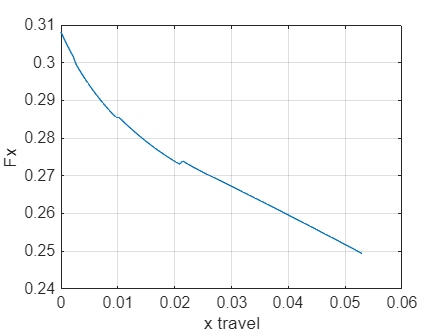


for i = 1 : length(x)

    Fx=[Fx F*cos(deg2rad(thet_vals(i)))*cos(deg2rad(phi_vals(i)))*cos(deg2rad(phi_vals(i)))];
end 

plot(x,Fx)
grid on 
xlabel('x travel')
ylabel('Fx')